syms r dt W;
syms delta;
%delta = sqrt(2*r^2);
vl0 = 2/10;
vr0 = -2/15;
vl1 = 1/15;
vr1 = 2/10;
R = W/2 * ((vr1+vl1)/(vr1-vl1))

$$R = W$$

theta_j = R * dt / (15*W);
s = R * theta_j

$$s = \frac{W\,\mathrm{dt}}{15}$$

syms theta_i; % = 2*dt/(15*W);
R = W;

pix = 0;
piy = -R;
pjx = delta;
pjy = -(R+r);
pix_ = R*sin(theta_i);
piy_ = -R*cos(theta_i);
d_ = sqrt((pjx - pix_)^2 + (pjy - piy_)^2);
d  = sqrt((pjx - pix)^2 + (pjy - piy)^2);
eq = d_ - d;
disp(eq);

$$\sqrt{{\left(W+r-W\,\cos\left(\theta_{i}\right)\right)}^{2}+{\left(\delta -W\,\sin\left(\theta_{i}\right)\right)}^{2}}-\sqrt{\delta^{2}+r^{2}}$$

disp(diff(eq, delta));

$$\frac{2\,\delta -2\,W\,\sin\left(\theta_{i}\right)}{2\,\sqrt{{\left(W+r-W\,\cos\left(\theta_{i}\right)\right)}^{2}+{\left(\delta -W\,\sin\left(\theta_{i}\right)\right)}^{2}}}-\frac{\delta }{\sqrt{\delta^{2}+r^{2}}}$$

syms a b;
eqq = expand(subs(eq, [W*sin(theta_i) (W+r-W*cos(theta_i))^2], [b a]));
sdiff = simplify(diff(eqq, delta));
disp(sdiff <= 0);

$$-\frac{\delta }{\sqrt{\delta^{2}+r^{2}}}-\frac{b-\delta }{\sqrt{b^{2}-2\,b\,\delta +\delta^{2}+a}}\leq 0$$


xs = (sqrt(2)*.085:.01:1);
old = [W r theta_i]

$$old = \left(\begin{array}{ccc} W & r & \theta_{i} \end{array}\right)$$

new = [0.14 0.085 2*0.1/(15*.14)]

new =                       0.14                     0.085        0.0952380952380952


f = vpa(subs(diff(eq, delta), old, new))

$$f = \frac{0.5\,\left(2.0\,\delta -0.026626372523731349777439430794526\right)}{\sqrt{{\left(\delta -0.013313186261865674888719715397263\right)}^{2}+0.0073332574631547965594949569421185}}-\frac{1.0\,\delta }{\sqrt{\delta^{2}+0.007225}}$$

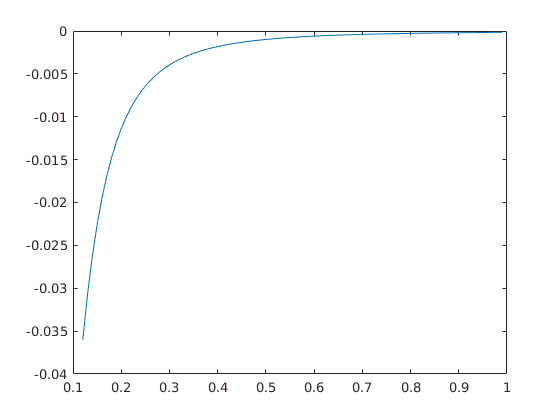

plot(xs, vpa(subs(f, delta, xs)))